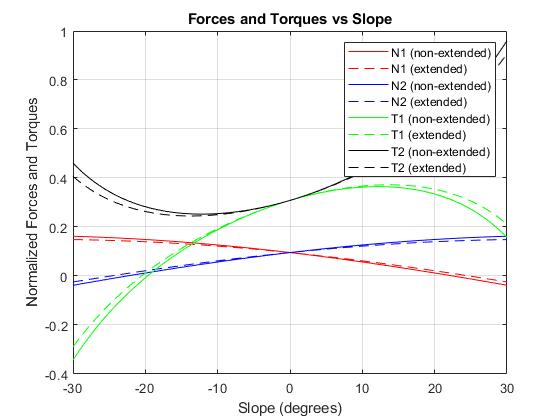

clear vars
clc
close all

theta = deg2rad(20); % Slope (rad)
m = 670; %kg, total (max) rover mass (1 crew)
g = 1.62; %m/s^2, accel due to gravity on the Mars, Moon (1.62) and Earth (9.8)


slope = -30:0.05:30;
%non extended
h_ne = 0.5;
l_ne = 2;
ax = 0.5;
a_ne = 1;
r = 0.3;
N1_list_ne = zeros(1,length(slope));
N2_list_ne = zeros(1,length(slope));
T_R_list_ne = zeros(1,length(slope));
T_F_list_ne = zeros(1,length(slope));
%extended
h_e = 0.6;
l_e = 2.6;
a_e = 1.3;
N1_list_e = zeros(1,length(slope));
N2_list_e = zeros(1,length(slope));
T_R_list_e = zeros(1,length(slope));
T_F_list_e = zeros(1,length(slope));

%non extended
for i = 1: length(slope)
    N1_list_ne(i) = m*g*((1-(a_ne/l_ne))*cosd(slope(i))-((h_ne/l_ne)+(r/l_ne))*sind(slope(i))-(ax/g))/2;
    N2_list_ne(i) = m*g*((a_ne/l_ne)*cosd(slope(i))+((h_ne/l_ne)+(r/l_ne))*sind(slope(i))-(ax/g))/2;
    T_F_list_ne(i) = (N1_list_ne(i)/(N1_list_ne(i)+N2_list_ne(i)))*m*g*sind(slope(i))+m*ax;
    T_R_list_ne(i) = (N2_list_ne(i)/(N1_list_ne(i)+N2_list_ne(i)))*m*g*sind(slope(i))+m*ax; 
end
%extended
for i = 1: length(slope)
    N1_list_e(i) = m*g*((1-(a_e/l_e))*cosd(slope(i))-((h_e/l_e)+(r/l_e))*sind(slope(i))-(ax/g))/2;
    N2_list_e(i) = m*g*((a_e/l_e)*cosd(slope(i))+((h_e/l_e)+(r/l_e))*sind(slope(i))-(ax/g))/2;
    T_F_list_e(i) = (N1_list_e(i)/(N1_list_e(i)+N2_list_e(i)))*m*g*sind(slope(i))+m*ax;
    T_R_list_e(i) = (N2_list_e(i)/(N1_list_e(i)+N2_list_e(i)))*m*g*sind(slope(i))+m*ax; 
end

plot(slope,N1_list_ne./(m*g),'red')
hold on
plot(slope,N1_list_e./(m*g),'--red')
hold on
plot(slope,N2_list_ne./(m*g),'blue')
hold on
plot(slope,N2_list_e./(m*g),'--blue')
hold on
plot(slope,T_F_list_ne./(m*g),'green')
hold on
plot(slope,T_F_list_e./(m*g),'--green')
hold on
plot(slope, T_R_list_ne./(m*g), 'black')
hold on
plot(slope, T_R_list_e./(m*g), '--black')
hold off
legend('N_1/mg','N_2/mg','T_{F}/mg','T_{R}/mg')
xlabel('Slope (degrees)')
ylabel("Normalized Forces and Torques")
% graph_title=strcat('(h=',num2str(h_ne),'m, l=',num2str(l_ne),'m, r=',num2str(r),'m, a=',num2str(a_ne),'m, ax=',num2str(ax),'m/s^2)');
title('Forces and Torques vs Slope')
legend('N1 (non-extended)','N1 (extended)','N2 (non-extended)','N2 (extended)','T1 (non-extended)','T1 (extended)','T2 (non-extended)','T2 (extended)')

grid on